%第一次作业习题1
clc, clear, close all;



%  曲线拟合
input = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10]; % 样本属性值
target = [0, 1, 2, 3, 4, 3, 2, 1, 2, 3, 4]; % 样本目标标签值


% newff 函数在2010b 之后已经弃用，现用 feedforwardnet (fitnet) 函数
% net = newff([0 10],[5 1],{'tansig' 'purelin'});



% 创建网络
tranFcn = 'traingd'; % 选择训练函数（学习规则）
hiddenLayerSize = 10; % 隐含层神经元的数目
net = feedforwardnet(hiddenLayerSize,tranFcn);





% 网络参数设置
net.layers{1}.transferFcn = 'tansig'; % 隐含层的激活函数
net.layers{2}.transferFcn = 'purelin'; % 输出层的激活函数
net.trainparam.show = 50; % 每次循环50次
net.trainParam.epochs = 500; % 最大循环500次
net.trainparam.goal = 0.01; % 期望目标误差最小值


% 初始网络预测
%Configure：配置网络输入和输出,以达到最好的匹配输入和目标数据
net = configure(net,input,target);
pred1 = net(input)

pred1 =     0.7302    0.8765    3.2279    3.8371    3.8490    4.9379    5.7827    3.4415    0.8934    0.0003   -0.4577


%pred1为所对应的input的初始网络预测值



% 训练网络并预测
net = train(net, input, target);
pred2 = net(input)

pred2 =    -0.0297    0.9146    2.1930    2.8911    2.5550    3.1300    3.4433    1.0777    1.9242    3.6323    3.9968


%pred2为所对应的input的训练后网络预测值

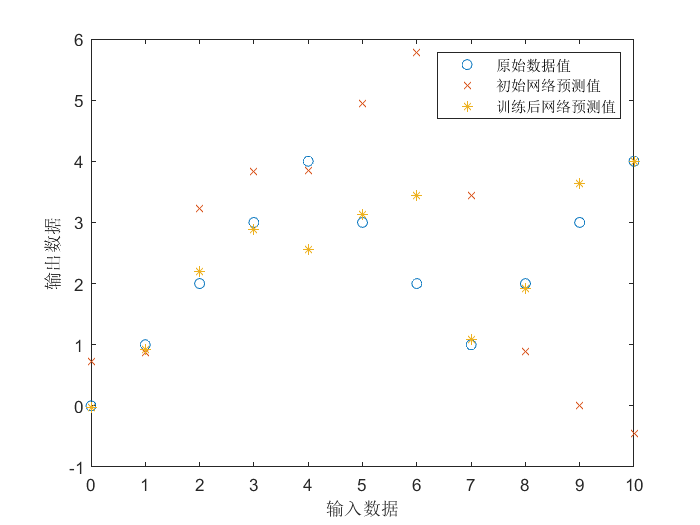


% 绘图
plot(input, target, 'o', input, pred1, 'x', input, pred2, '*')
legend('原始数据值','初始网络预测值','训练后网络预测值')
xlabel '输入数据'
ylabel '输出数据'

save('net.mat','net');       % 将网络net保存为.mat文件，后面可直接调用



load('net.mat');     % 导入之前保存的网络
%预测函数
fprintf('请输入测试数据x');

请输入测试数据x

x=[1 5 1]

x =      1     5     1


fprintf('输出测试结果y');

输出测试结果y

y=sim(net,x)

y =     0.9146    3.1300    0.9146
